%load audio file
filename = 'speech.wav';
[s,Fs] = audioread(filename);

%user defined function
a=2;
F = 250*a;
y = s *cos(2*pi*F/Fs)

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


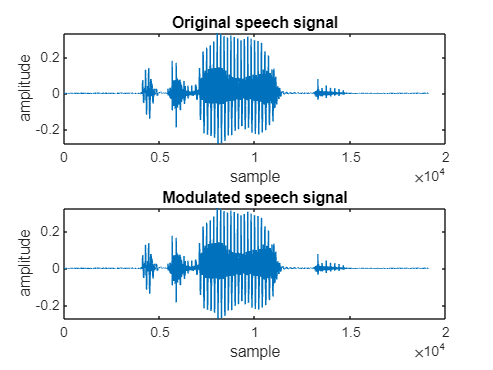

subplot(2,1,1);
plot(s);
title('Original speech signal');
xlabel('sample');
ylabel('amplitude');
subplot(2,1,2);
plot(y);
title('Modulated speech signal');
xlabel('sample');
ylabel('amplitude');

S = fft(s);
Y = fft(y);
freq = linspace(0,Fs,length(S));
subplot(2,1,1);
plot(freq,abs(S));
title('spectrum of Original speech signal');
xlabel('frequency');
ylabel('Magnitude');
subplot(2,1,2);
plot(freq,Y);

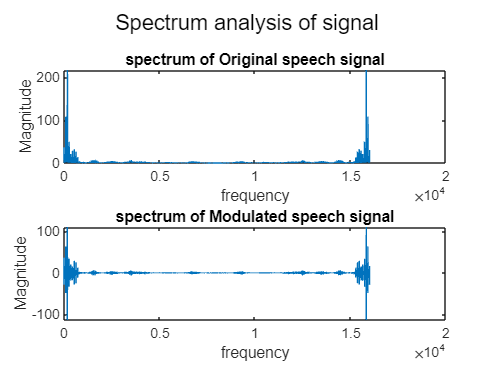

title('spectrum of Modulated speech signal');
xlabel('frequency');
ylabel('Magnitude');
sgtitle("Spectrum analysis of signal");